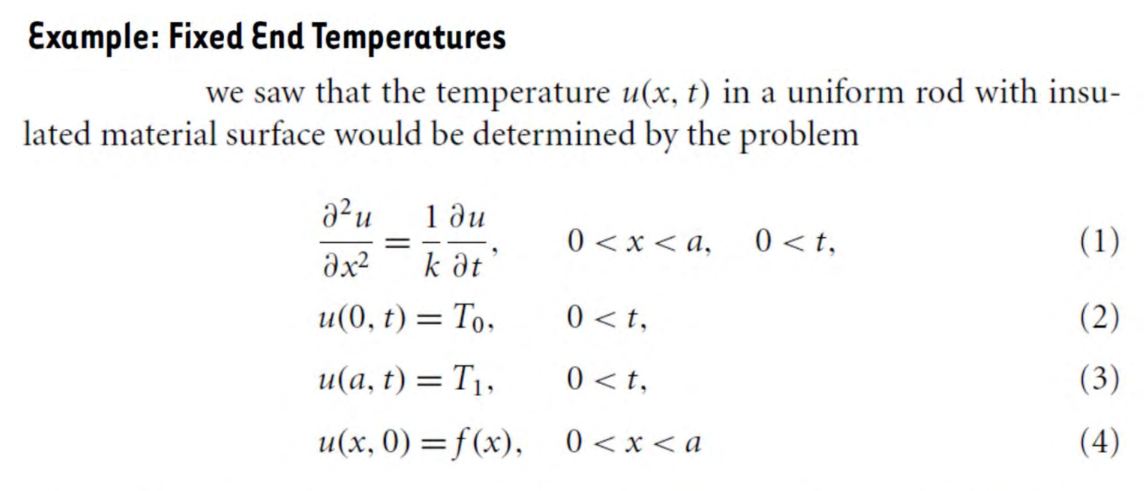

clear
clc
clf
syms x v(x) a T0 T1 D
assume(a,"positive")
SteadyS = D*diff(v,x,2) == 0

$$SteadyS(x) = \text{D}\,\frac{\partial^{2}}{\partial x^{2}}v\left(x\right)=0$$

C0 = v(0) == T0

$$C0 = v\left(0\right)=T_{0}$$

Ca = v(a) == T1

$$Ca = v\left(a\right)=T_{1}$$

v(x) = dsolve(SteadyS,[C0 Ca])

$$v(x) = T_{0}-\frac{x\,\left(T_{0}-T_{1}\right)}{a}$$

**Transient w(x,t)=u(x,t)-v(x)**

**Seperation part**

syms t w(x,t)
assume([a D],"positive")
HeatEq = diff(w,t) == D*diff(w,x,2)

$$HeatEq(x, t) = \frac{\partial }{\partial t}w\left(x,t\right)=\text{D}\,\frac{\partial^{2}}{\partial x^{2}}w\left(x,t\right)$$

BC0 = w(0,t) == 0

$$BC0 = w\left(0,t\right)=0$$

BCL = w(a,t) == 0

$$BCL = w\left(a,t\right)=0$$

syms T(t) X(x)
SepVar = subs(HeatEq,w(x,t),X(x)*T(t));
SepVar = SepVar/(D*X(x)*T(t))

$$SepVar(x, t) = \frac{\frac{\partial }{\partial t}T\left(t\right)}{\text{D}\,T\left(t\right)}=\frac{\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)}{X\left(x\right)}$$

var = children(SepVar);
BCx0 = subs(BC0,w(0,t),X(0))

$$BCx0 = X\left(0\right)=0$$

BCxa = subs(BCL,w(a,t),X(a))

$$BCxa = X\left(a\right)=0$$

`Seperation`

syms lambda
assume(lambda,"positive")
eqT = var(1) == -lambda^2

$$eqT = \frac{\frac{\partial }{\partial t}T\left(t\right)}{\text{D}\,T\left(t\right)}=-\lambda^{2}$$

eqX = var(2) == -lambda^2

$$eqX = \frac{\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)}{X\left(x\right)}=-\lambda^{2}$$

T(t,lambda) = dsolve(eqT)

$$T(t, lambda) = C_{1}\,{\mathrm{e}}^{-\text{D}\,\lambda^{2}\,t}$$

X(x,lambda) = dsolve(eqX,BCx0)

$$X(x, lambda) = -C_{1}\,\sin\left(\lambda \,x\right)$$

constantX = setdiff(symvar(X(x,lambda)),sym(['C',x,lambda]));
X(x,lambda) = subs(-X(x,lambda),constantX,sym('C2'))

$$X(x, lambda) = C_{2}\,\sin\left(\lambda \,x\right)$$

sln = X(a,lambda) == 0;

**Finding lambda**

[lambda,parameters,conditions] = solve(sln,lambda,"ReturnConditions",true);
n = sym("n",["integer","positive"]);
lambda = subs(lambda,parameters,n)

$$lambda = \frac{\pi \,n}{a}$$

syms b_n ustruct(x,t,n);
expT(t,n) = subs(T(t,lambda),[lambda,sym('C1')],[lambda,sym('1')]);
sinX(x,n) = subs(X(x,lambda),[lambda,sym('C2')],[lambda,b_n]);
ustruct(x,t,n) = collect(sinX(x,n)*expT(t,n),["sin" "exp"])

$$ustruct(x, t, n) = b_{n}\,\sin\left(\frac{\pi \,n\,x}{a}\right)\,{\mathrm{e}}^{-\frac{\text{D}\,n^{2}\,t\,\pi^{2}}{a^{2}}}$$

**Fourier series part**

syms x t n b(n) phi(x)
assume(n,"integer")
phi(x) = 0-v(x);
ft0 = subs(ustruct(x,0,n),sym("b_n"),1)

$$ft0 = \sin\left(\frac{\pi \,n\,x}{a}\right)$$

b(n) = simplify(2/a*int(phi(x)*ft0,x,[0 a]))

$$b(n) = -\frac{2\,\left(T_{0}-{\left(-1\right)}^{n}\,T_{1}\right)}{n\,\pi }$$

D = 0.1

D = 0.1000

N = 1

N = 1

T0 = 20

T0 = 20

T1 = 80

T1 = 80

a = 1

a = 1

tau = 6

tau = 6

v(x) = subs(v,sym(["a" "T0" "T1"]),[a T0 T1])

$$v(x) = 60\,x+20$$

b(n) = subs(b,sym(["T0" "T1"]),[T0 T1])

$$b(n) = \frac{2\,\left(80\,{\left(-1\right)}^{n}-20\right)}{n\,\pi }$$

heatStruct = ustruct

$$heatStruct(x, t, n) = b_{n}\,\sin\left(\frac{\pi \,n\,x}{a}\right)\,{\mathrm{e}}^{-\frac{\text{D}\,n^{2}\,t\,\pi^{2}}{a^{2}}}$$

heatstructEmb(x,t,n) = subs(heatStruct,sym(["b_n" "a" "D"]),[b a D]);

**Solution**

heatSolN = v(x)+simplify(symsum(heatstructEmb,n,1,N))

$$heatSolN(x, t) = 60\,x-\frac{200\,{\mathrm{e}}^{-\frac{t\,\pi^{2}}{10}}\,\sin\left(\pi \,x\right)}{\pi }+20$$

heatstructEmb(x,t,n) = v(x)+symsum(heatstructEmb,n,1,inf)

$$heatstructEmb(x, t, n) = 60\,x+\frac{2\,\left(\sum_{n=1}^{\infty }\frac{\sin\left(\pi \,n\,x\right)\,{\mathrm{e}}^{-\frac{n^{2}\,t\,\pi^{2}}{10}}\,\left(80\,{\left(-1\right)}^{n}-20\right)}{n}\right)}{\pi }+20$$

**3D plot**

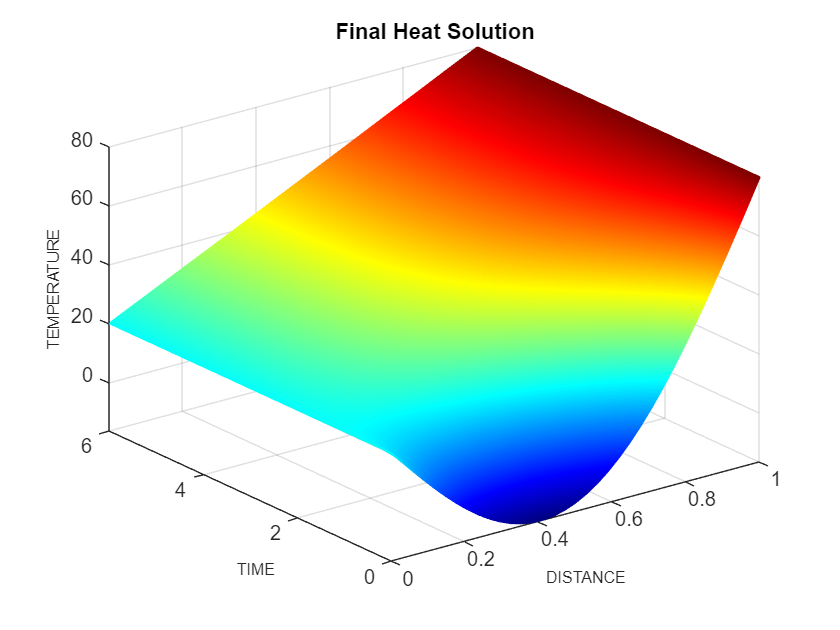

figure
colormap jet
fsurf(heatSolN,[0 a 0 tau],"EdgeColor","interp")
title("Final Heat Solution")
xlabel( 'DISTANCE', 'Fontsize',8);
ylabel('TIME', 'Fontsize',8)
zlabel('TEMPERATURE', 'Fontsize',8)

**Heat profile different times**

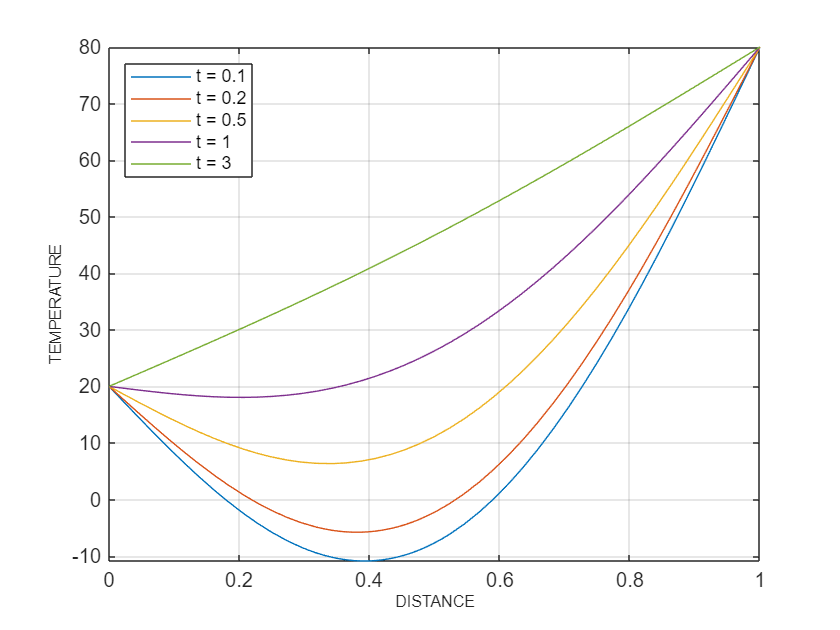

clf
tm = [0.1 0.2 0.5 1 3];
for i = 1:length(tm)
    sn = matlabFunction(heatSolN(x,tm(i)));
    fplot(sn, [0 a])
    grid on, hold on
end
xlabel('DISTANCE', 'Fontsize',8);
ylabel('TEMPERATURE','Fontsize',8)
legend('t = 0.1','t = 0.2','t = 0.5','t = 1','t = 3','Location','northwest')

**Heat profile at various**

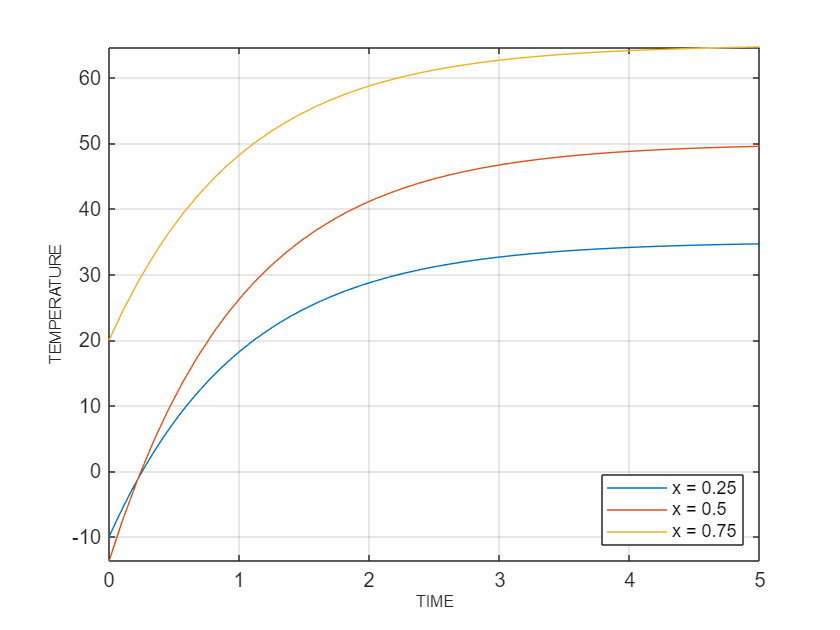

clf
dst = [0.25 0.5 0.75];
for i = 1:length(dst)
    sn = matlabFunction(heatSolN(dst(i),t));
    fplot(sn, [0 5])
    grid on, hold on
end
xlabel('TIME','Fontsize',8);
ylabel('TEMPERATURE', 'Fontsize',8)
legend('x = 0.25','x = 0.5', 'x = 0.75','Location','southeast')